%%LQG lazo cerrado
A=[0 1 0; 0 0 1;0 -2 -3];
B=[0;0;1];
C=[1 0 0];
D=5;
%1er paso LQR
Qy=1000;
Ru=0.001;

Q=C'*Qy*C;
R=D'*Qy*D+Ru;
N=C'*Qy*D;

K=lqr(A,B,Q,R,N);
Kr = inv(-(C-D*K)*(A-B*K)^-1*B+D)

Kr = 0.2000


%2do paso LQG
Gw=eye(3); %Matriz de dinamica de ruido
Qw=0.01*eye(3) %Covarianza de w

Qw =     0.0100         0         0
         0    0.0100         0
         0         0    0.0100


Vv=0.0001*eye(1) %Covarianza de v

Vv = 1.0000e-04

L=lqe(A,Gw,C,Qw,Vv)

L =    10.6229
    6.4232
   -3.0990



%3er paso, Cerrar el Lazo
ACL=[A -B*K; L*C A-B*K-L*C]

ACL =          0    1.0000         0         0         0         0
         0         0    1.0000         0         0         0
         0   -2.0000   -3.0000   -0.2000   -0.0000   -0.0000
   10.6229         0         0  -10.6229    1.0000         0
    6.4232         0         0   -6.4232         0    1.0000
   -3.0990         0         0    2.8990   -2.0000   -3.0000


BCL=[B*Kr; B*Kr]

BCL =          0
         0
    0.2000
         0
         0
    0.2000


CCL=[C -D*K]

CCL =     1.0000         0         0   -1.0000   -0.0000   -0.0000


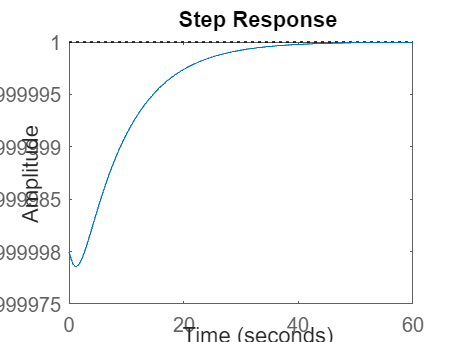

DCL=[D*Kr];

GCL=ss(ACL,BCL,CCL,DCL);
step(GCL)